## 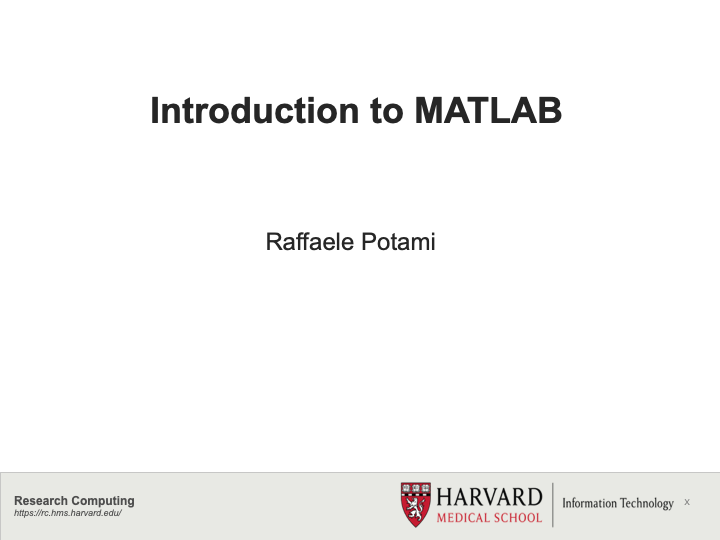

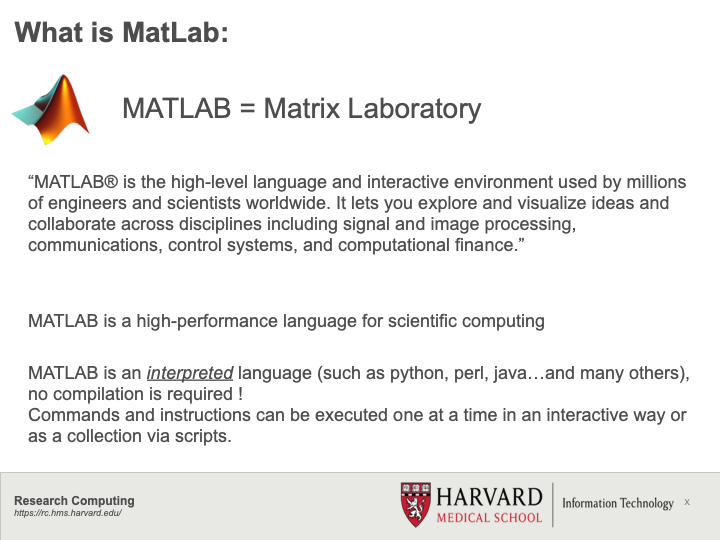

## 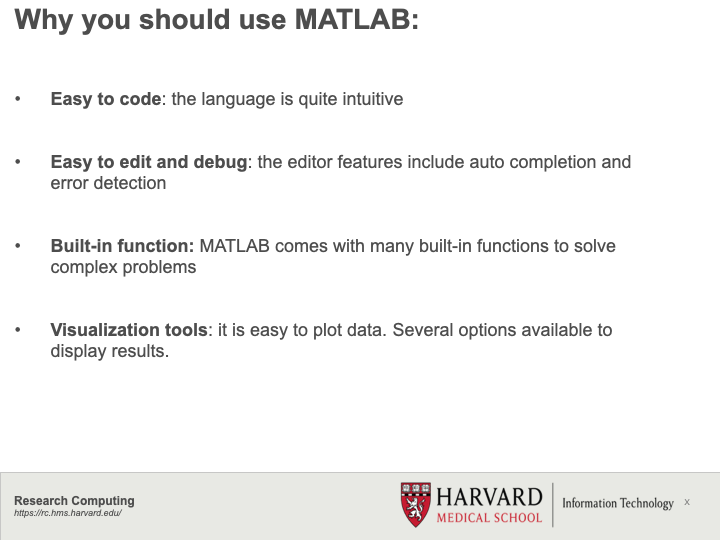

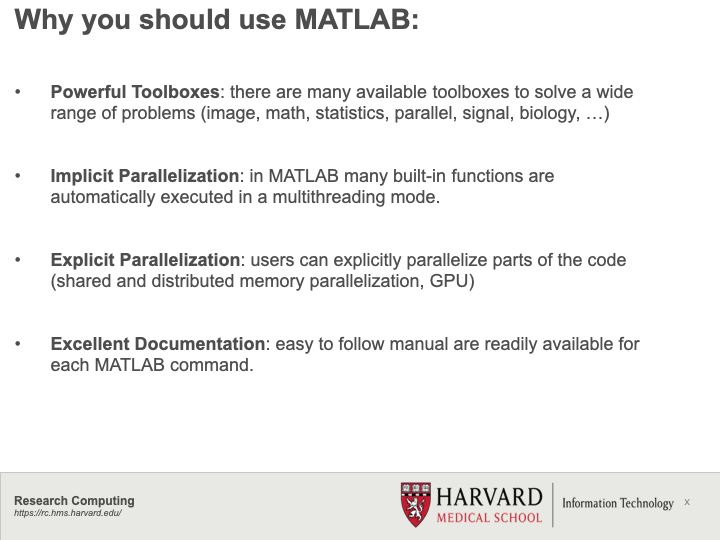

## 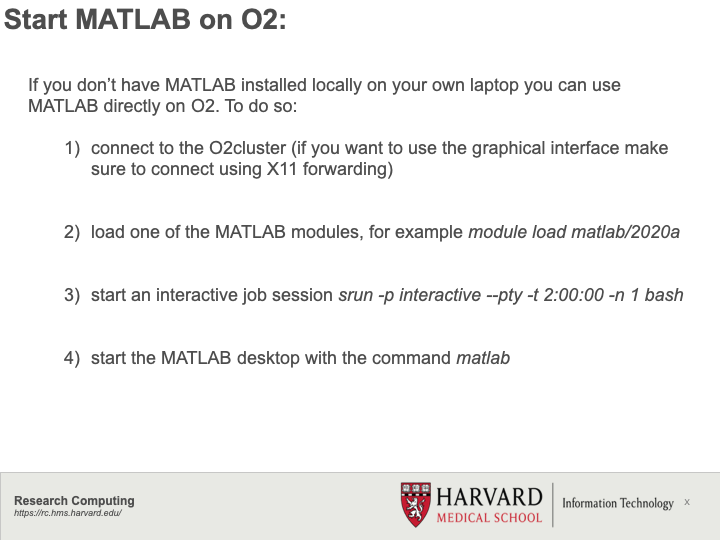

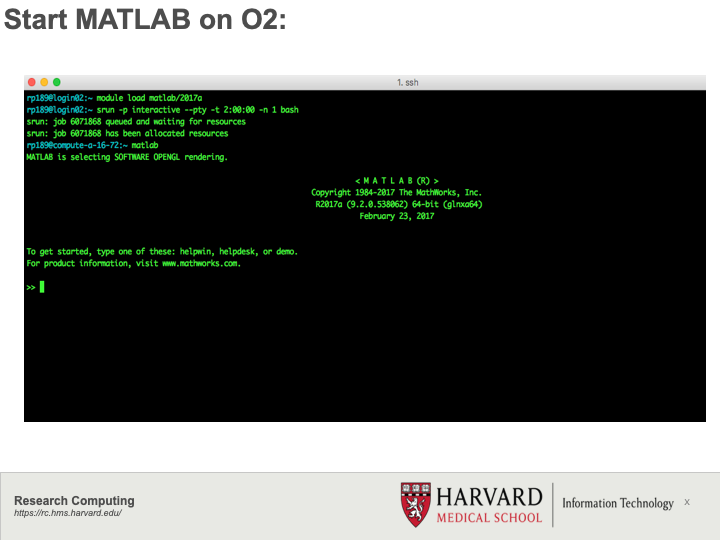

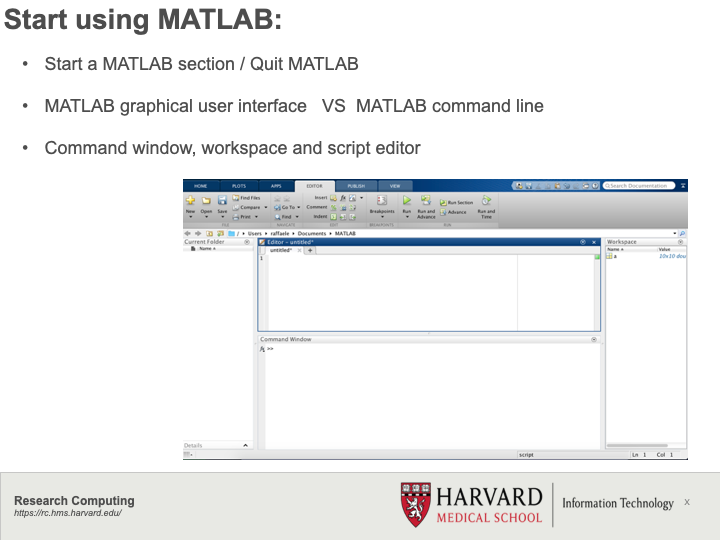

## **Basic commands and functionalities.**

#### **Getting help:**

Three commands available: help, doc, lookfor ( and Google)

help sum  %short manual

 sum Sum of elements.
    S = sum(X) is the sum of the elements of the vector X. If X is a matrix,
    S is a row vector with the sum over each column. For N-D arrays, 
    sum(X) operates along the first non-singleton dimension.
 
    S = sum(X,'all') sums all elements of X.
 
    S = sum(X,DIM) sums along the dimension DIM.
 
    S = sum(X,VECDIM) operates on the dimensions specified in the vector 
    VECDIM. For example, sum(X,[1 2]) operates on the elements contained in
    the first and second dimensions of X.
 
    S = sum(...,OUTTYPE) specifies the type in which the 
    sum is performed, and the type of S. Available options are:
 
    'double'    -  S has class double for any input X
    'native'    -  S has the same class as X
    'default'   -  If X is floating point, that is double or single,
                   S has the same class as X. If

doc sum   %long manual
lookfor sum  %search for

trace                          - Sum of diagonal elements.
hypot                          - Robust computation of the square root of the sum of squares
cumsum                         - Cumulative sum of elements.
groupsummary                   - Summary computations by group.
movsum                         - Moving sum value.
sum                            - Sum of elements.
dbcont                         - Resume execution
movsum                         - Moving sum value.
sum                            - Sum of durations.
getSummaryLabels               - Get summary labels for min, max, true, and false
cumsum           

#### **Using Variables: **

MATLAB automatically assign type; functions to convert across different types (int8, int16, double, single, etc.). MATLAB is case sensitive !

You can reassign variable

n=4;
m=1/3;
str='this is a string'

str = 'this is a string'


whos

  Name        Size            Bytes  Class     Attributes

  INIT      100x1               800  double              
  ans         1x1                 8  double              
  m           1x1                 8  double              
  n           1x1                 8  double              
  str         1x16               32  char                



n=int16(n)

n = int16
4

whos n

  Name      Size            Bytes  Class    Attributes

  n         1x1                 2  int16              




m=n*m;
fprintf('did you expect %f',m)

did you expect 1.000000


m=1/3;
m=double(n)*m

m = 1.3333

#### Digit Precision 

MATLAB uses double precision by default, even if it displays only a few digits

%%
var1=rand;
disp(var1)

    0.7094



format long  %display more digits
disp(var1)

   0.709364830858073



var1short=single(var1);%convert to single precision
disp(var1short)

   0.7093648



format short

#### Creating vector and matrix

Vectors and matrices can be created manually

clear variables;
t1=[1 2 3 4 5] %row vector

t1 =      1     2     3     4     5


t2=[1;2;3;4;5] %column vectort1*t2

t2 =      1
     2
     3
     4
     5


or with implicit loops

t3=1:5 %implicit loop, 

t3 =      1     2     3     4     5


length(t1)

ans = 5

t4=1:0.5:5

t4 =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


length(t4)

ans = 9

t5=linspace(1,5,10)

t5 =     1.0000    1.4444    1.8889    2.3333    2.7778    3.2222    3.6667    4.1111    4.5556    5.0000


or using pre-built functions

f=rand(1,10)

f =     0.7547    0.2760    0.6797    0.6551    0.1626    0.1190    0.4984    0.9597    0.3404    0.5853


a=zeros(3)

a =      0     0     0
     0     0     0
     0     0     0


b=ones(3)

b =      1     1     1
     1     1     1
     1     1     1


c=rand(3);
d=eye(3)

d =      1     0     0
     0     1     0
     0     0     1


e=diag([1 2 3])

e =      1     0     0
     0     2     0
     0     0     3


it's possible to combine together two or more matrices or vectors

abcd=[a b;c d]

abcd =          0         0         0    1.0000    1.0000    1.0000
         0         0         0    1.0000    1.0000    1.0000
         0         0         0    1.0000    1.0000    1.0000
    0.2238    0.5060    0.9593    1.0000         0         0
    0.7513    0.6991    0.5472         0    1.0000         0
    0.2551    0.8909    0.1386         0         0    1.0000


[m,n]=size(abcd)

m = 6

n = 6

#### Operating with vectors and matrices

It is possible to obtain an array value by providing the desired index or range:

disp(c(3,1)) 

    0.2551



disp(c(3))

    0.2551



disp(c(:,3))

    0.9593
    0.5472
    0.1386



disp(c(1:2,1:2))

    0.2238    0.5060
    0.7513    0.6991



or to modify part of the array 

c(2,2)=100;
c(3,:)=0;
disp(c)

    0.2238    0.5060    0.9593
    0.7513  100.0000    0.5472
         0         0         0



attention should be paid when executing algebric operation between arrays.

#### Element-wise and matrices operations

clear variables;
A=ones(4);
B=rand(4);
sin(A)

ans =     0.8415    0.8415    0.8415    0.8415
    0.8415    0.8415    0.8415    0.8415
    0.8415    0.8415    0.8415    0.8415
    0.8415    0.8415    0.8415    0.8415


A+A

ans =      2     2     2     2
     2     2     2     2
     2     2     2     2
     2     2     2     2


A*3

ans =      3     3     3     3
     3     3     3     3
     3     3     3     3
     3     3     3     3


A.*B

ans =     0.1493    0.8143    0.1966    0.3517
    0.2575    0.2435    0.2511    0.8308
    0.8407    0.9293    0.6160    0.5853
    0.2543    0.3500    0.4733    0.5497


which is different than

A*B

ans =     1.5018    2.3371    1.5370    2.3175
    1.5018    2.3371    1.5370    2.3175
    1.5018    2.3371    1.5370    2.3175
    1.5018    2.3371    1.5370    2.3175


A./B

ans =     6.6982    1.2281    5.0866    2.8437
    3.8834    4.1064    3.9827    1.2036
    1.1895    1.0761    1.6233    1.7086
    3.9326    2.8573    2.1129    1.8191


which is different than

A/B

ans =    -0.2708   -0.0120    0.9339    1.0162
   -0.2708   -0.0120    0.9339    1.0162
   -0.2708   -0.0120    0.9339    1.0162
   -0.2708   -0.0120    0.9339    1.0162


solving $\textrm{Ax}=b$


$$\textrm{inv}\left(A\right)\textrm{Ax}=\textrm{inv}\left(A\right)b$$



$$x=\textrm{inv}\left(A\right)b$$


clear variables; clc
A=rand(1000);
b=rand(1000,1);
C3=A\b;
C4=inv(A)*b;
max(C3-C4)

ans = 1.7142e-13

#### Examples of useful implicit functions

B=rand(5)

B =     0.3922    0.1484    0.1931    0.6684    0.5070
    0.4828    0.9338    0.9734    0.8565    0.5373
    0.0687    0.9966    0.6060    0.7064    0.7883
    0.9413    0.6861    0.0926    0.5653    0.5579
    0.2688    0.1546    0.1682    0.2034    0.1541


min(B)      % min by columns

ans =     0.0687    0.1484    0.0926    0.2034    0.1541


min(B,[],2) % min by row

ans =     0.1484
    0.4828
    0.0687
    0.0926
    0.1541


max(B)

ans =     0.9413    0.9966    0.9734    0.8565    0.7883


max(max(B))

ans = 0.9966


sum(B)

ans =     2.1538    2.9195    2.0333    3.0000    2.5446


sum(B,2)

ans =     1.9092
    3.7837
    3.1661
    2.8432
    0.9490


sum(sum(B))

ans = 12.6512

diag(B)

ans =     0.3922
    0.9338
    0.6060
    0.5653
    0.1541


Find index when value satisfy a given condition:

ind=find(B>0.5)

ind =      4
     7
     8
     9
    12
    13
    16
    17
    18
    19


[m,n]=find(B>0.5)

m =      4
     2
     3
     4
     2
     3
     1
     2
     3
     4


n =      1
     2
     2
     2
     3
     3
     4
     4
     4
     4


T=B>0.5  %return a matrix of 1 and 0

T = 5×5 logical array
   0   0   0   1   1
   0   1   1   1   1
   0   1   1   1   1
   1   1   0   1   1
   0   0   0   0   0


B2=B.*T %extract matrix with values > 0.5

B2 =          0         0         0    0.6684    0.5070
         0    0.9338    0.9734    0.8565    0.5373
         0    0.9966    0.6060    0.7064    0.7883
    0.9413    0.6861         0    0.5653    0.5579
         0         0         0         0         0


## Data visualization

#### Plot 1D data commands:  plot, scatter, loglog, semilogx, semilogy, plotyy, figure, axis, title, legend, xlabel,    …  

t=0:0.01:10;
x=rand(1,length(t));
y1 = 0.5*cos(pi/2*t);
y2 = x.*cos(pi/2*t);

figure
pict=plot(t,y1,'--',t,y2,'-')

pict =   2×1 Line array:

  Line
  Line


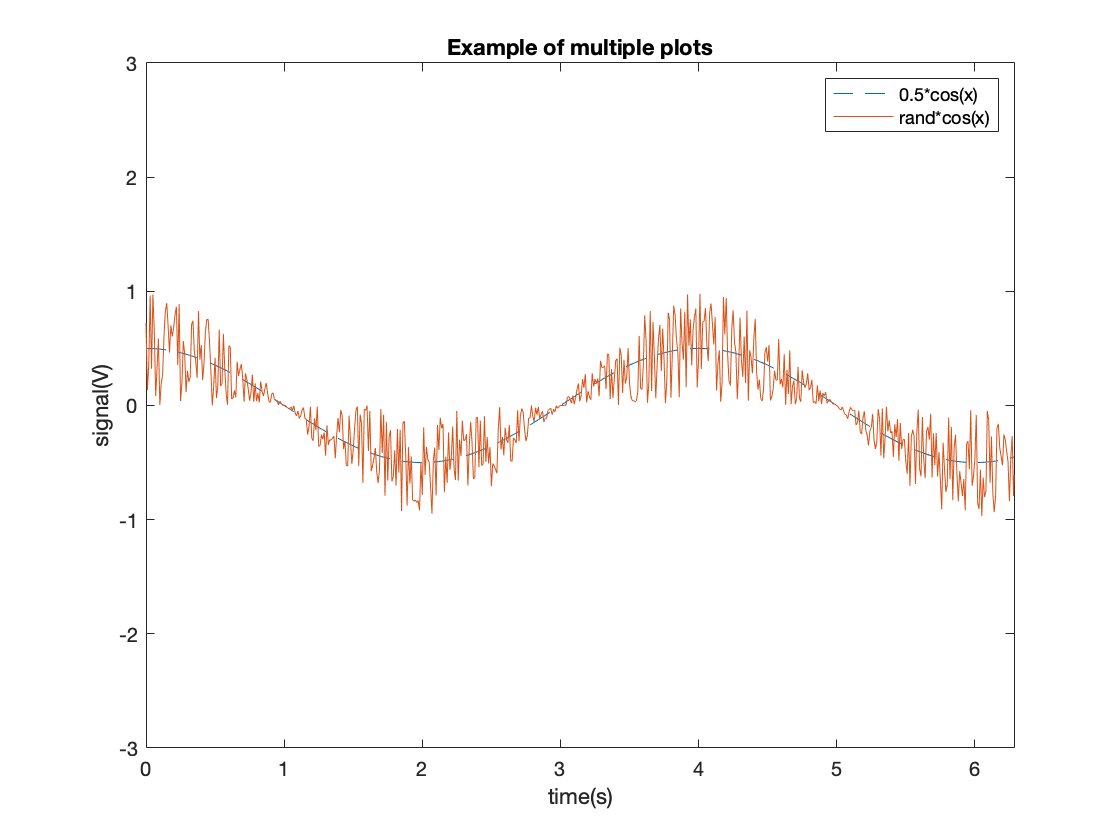

xlabel('time(s)')
ylabel('signal(V)')
legend('0.5*cos(x)','rand*cos(x)')
title('Example of multiple plots')
axis([0 2*pi -3 3])

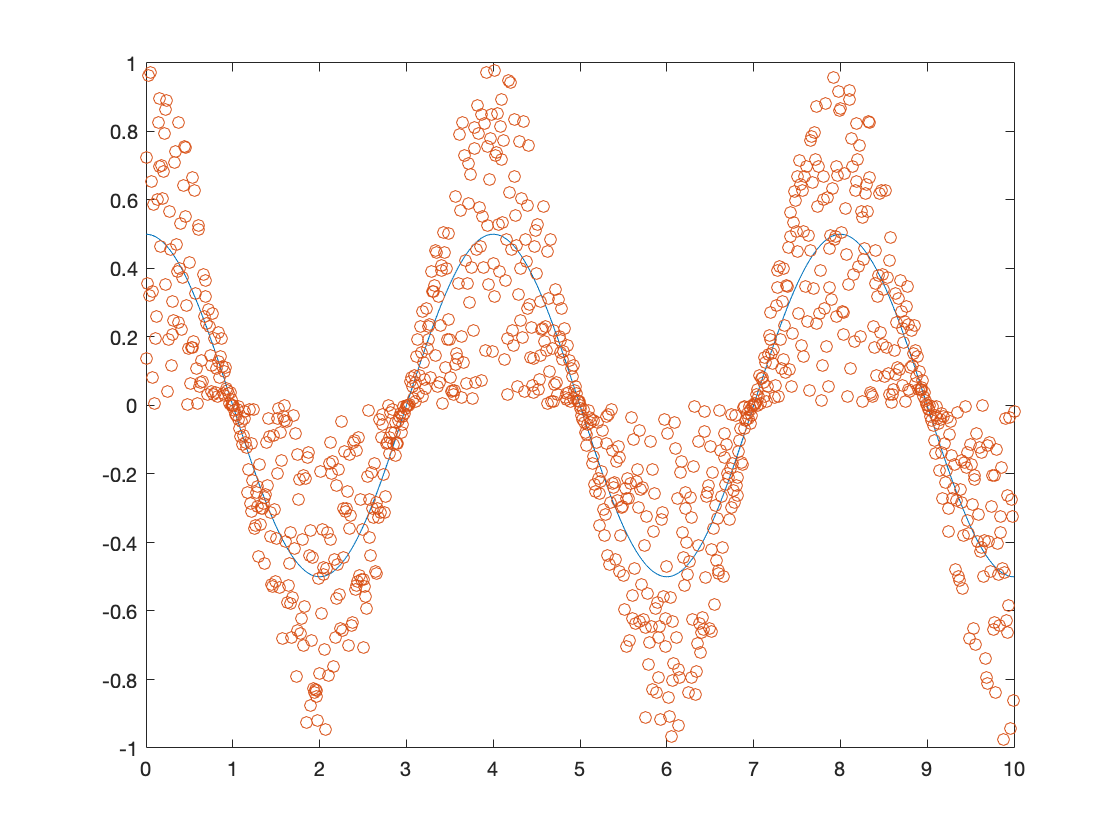

plot(t,y1)
hold on
scatter(t,y2)

#### Plot 2D data commands:  contour, contourf, pcolor, figure, … 

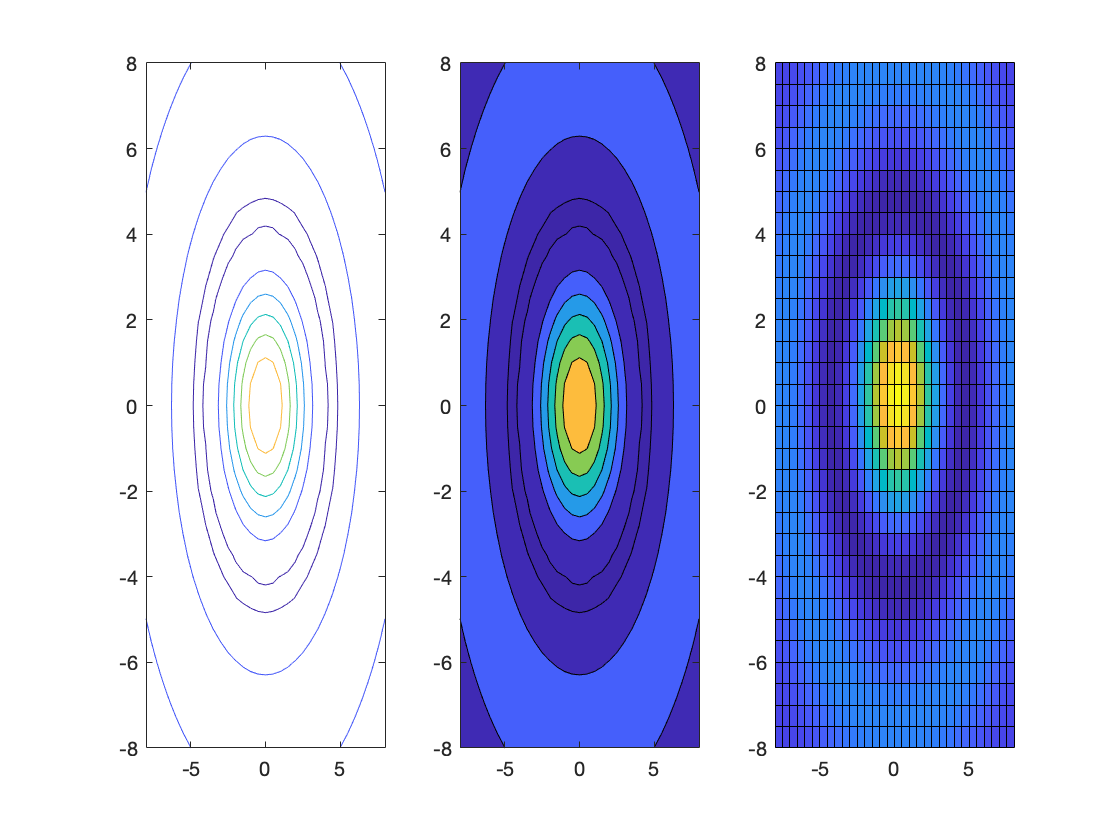

[X,Y] = meshgrid(-8:.5:8,-8:.5:8);
R = sqrt(X.^2 + Y.^2) + eps;
Z = sin(R)./R;
figure(1)
subplot(1,3,1)
contour(X,Y,Z)
subplot(1,3,2)
contourf(X,Y,Z)
subplot(1,3,3)
pcolor(X,Y,Z)

#### Plot 3D data commands:  contour3, plot3, surf, … 

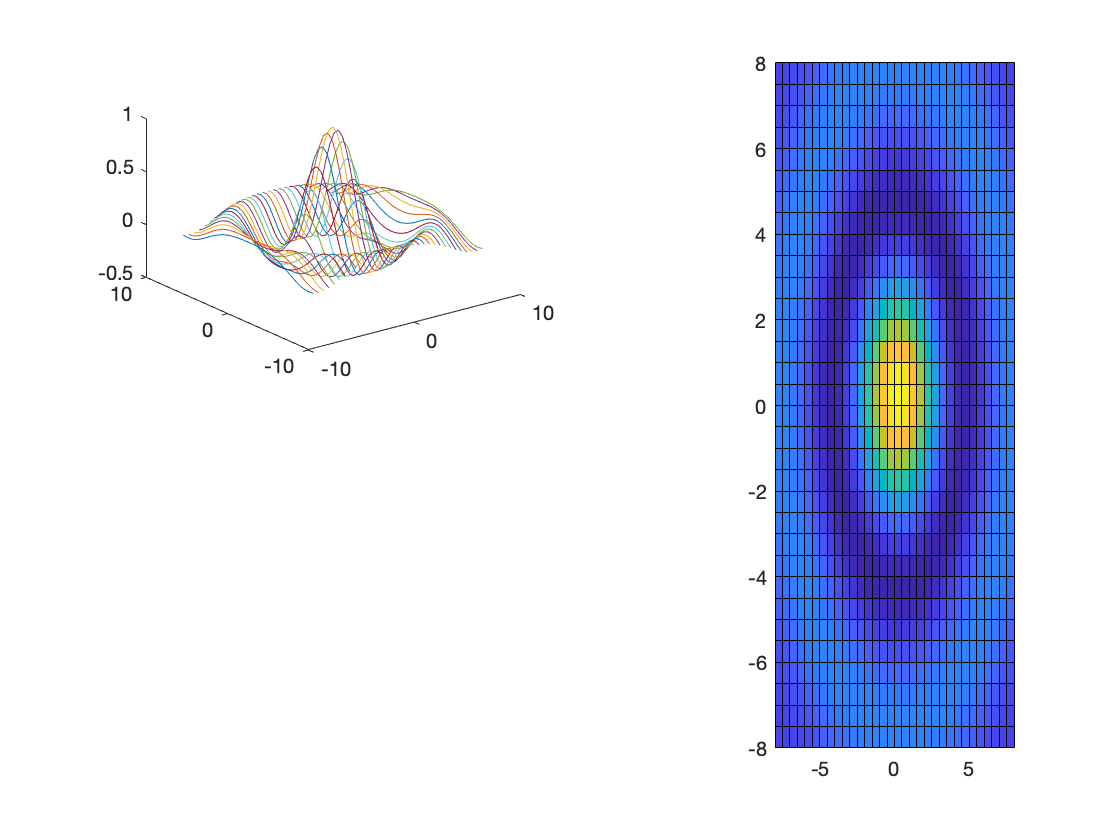

subplot(2,2,1)
plot3(X,Y,Z)

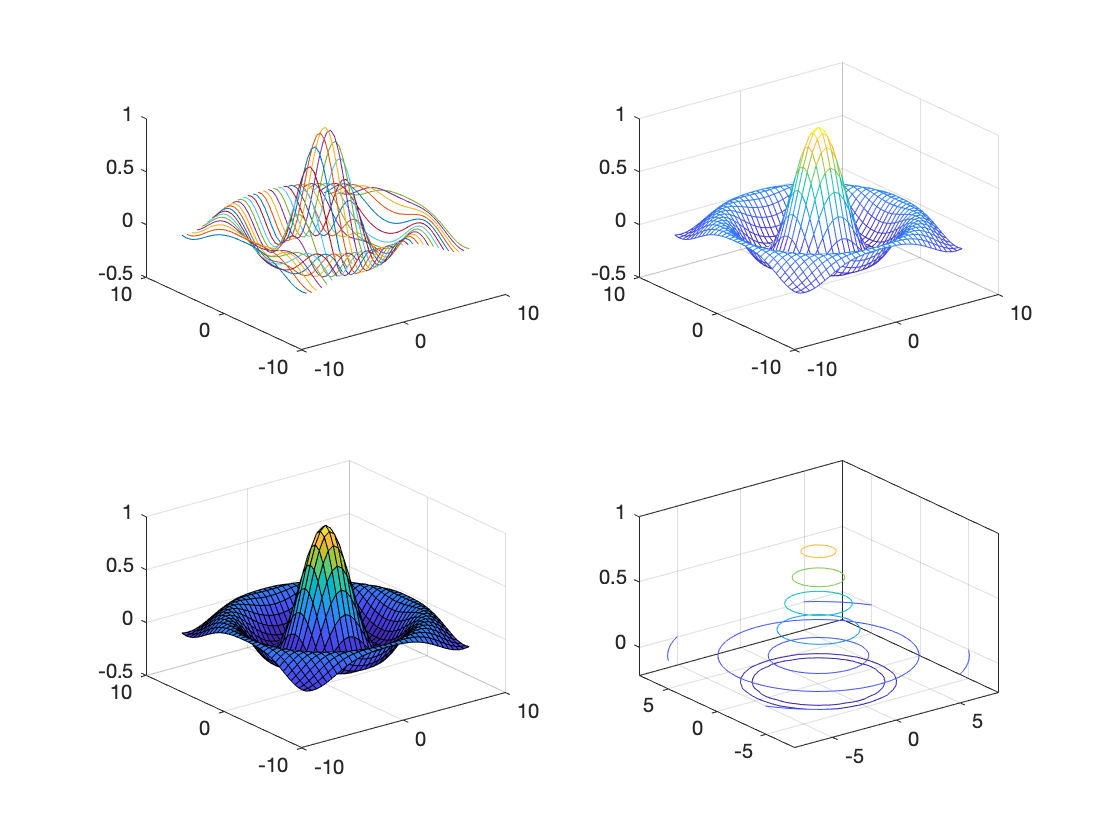

subplot(2,2,2)
mesh(X,Y,Z)
subplot(2,2,3)
surf(X,Y,Z)
subplot(2,2,4)
contour3(X,Y,Z)

#### And more ... 

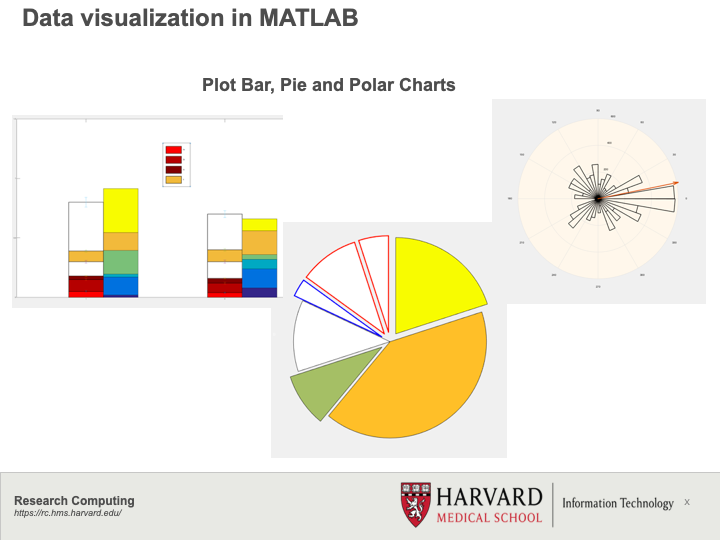

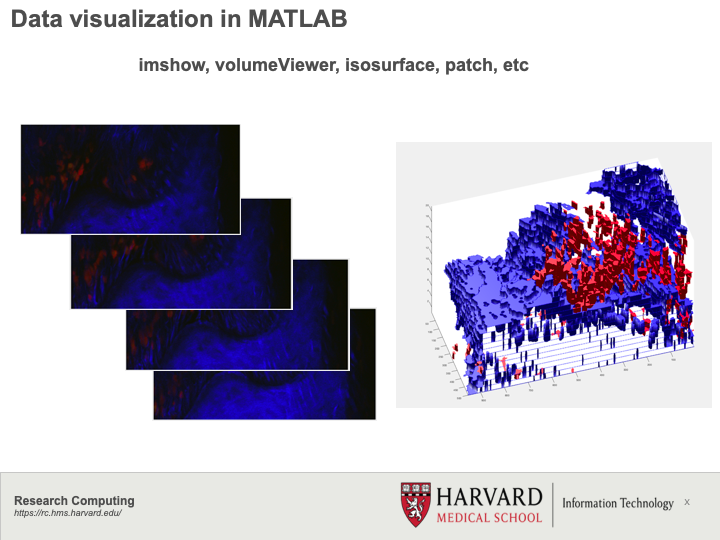

with **bar, errorbar, polarplot, quiver, pie, imshow, volumeViewer, isosurface, patch, ...**

## **Programming in MATLAB: Scripts and Functions:**

Scripts: are collections of MATLAB commands that can be executed as a single jobs.

Functions: are collections of MATLAB commands used to simplify scripts by generalizing parts with same functionalities. 

There are few major differences between functions and scripts: 

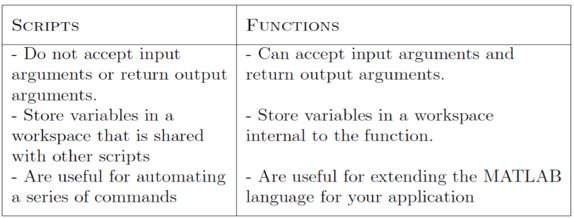

astring='today you are learning MATLAB';
number=123456;
[occur,locations]=searchit(astring,'a')

occur = 3

locations =      4    11    17


fprintf('number is still %d \n',number)

number is still 123456 


Useful construct with try-catch to handle an error without breaking the execution:

try
    B=inv([1 2 3; 4 5 6; 1 2 3 ]) %this is wrong
catch error
    error
    % do something else
end

B =    Inf   Inf   Inf
   Inf   Inf   Inf
   Inf   Inf   Inf


Measure elapsed time when executing code

clear all;clc
tic
pause(3)
toc

Elapsed time is 3.036334 seconds.


### Control flow commands:

Executes sections only when certain conditions are true with **IF** and **SWITCH**

flag=5;
if flag == 5
    disp('OK');
elseif flag < 9
    disp('Great');
else
    disp('Yes');
end

OK


flag=9;
switch flag
    case  5
        disp('OK')
    case  9
        disp('Great')
end

Great


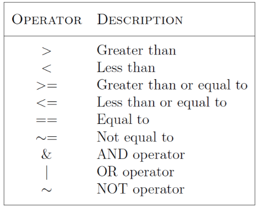

### Loop Commands:

Executes the same set of commands multiple times with **FOR** and **WHILE**.

for n=1:10
    disp(n)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



n=1;
while n < 10
    n=n+1
end

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n

n = 10

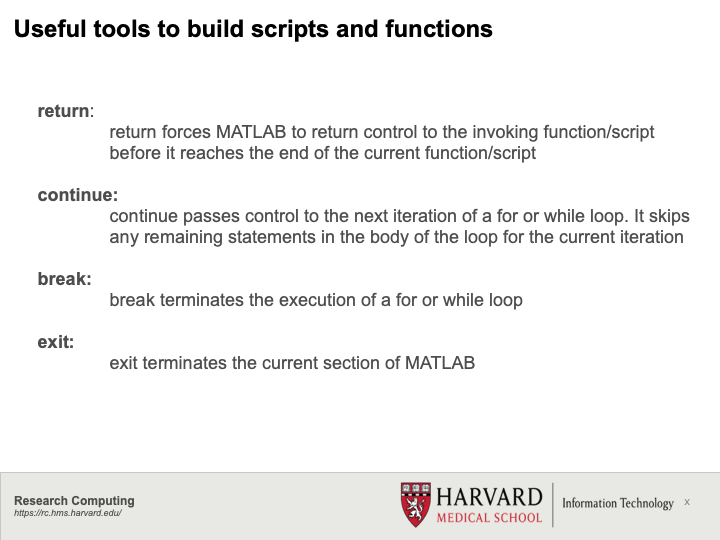

for n=1:10
    n
    if n == 5
        break;
    end
end

n = 1

n = 2

n = 3

n = 4

n = 5

n

n = 5

for n=1:10
    if n==5
        continue;
    end
    disp(n);
end

     1

     2

     3

     4

     6

     7

     8

     9

    10



val1=5;
val2=8;
multiply(val1,val2)

val1=5 not good


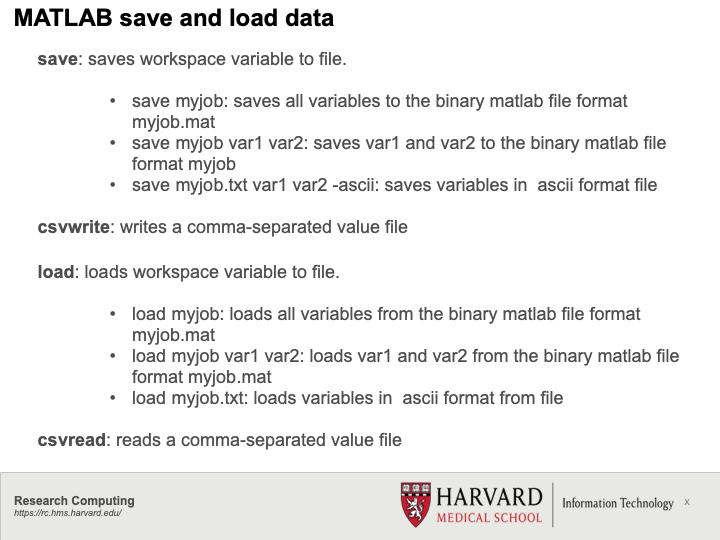

A=rand(10);
B=eye(10);
C=rand(10,1);
save myjob
clear variables

who


load myjob
who


Your variables are:

A     B     C     flag  n     val1  val2  



save myjob2 A
clear variables
load myjob2
who


Your variables are:

A  



save myjob3.txt A -ascii

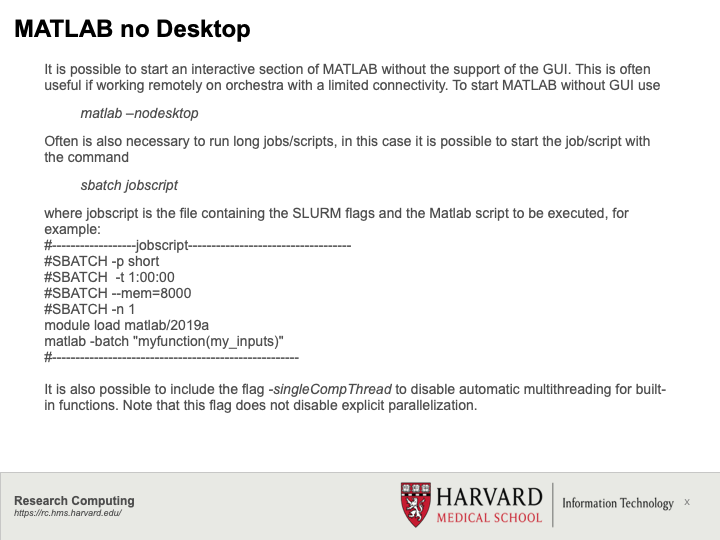

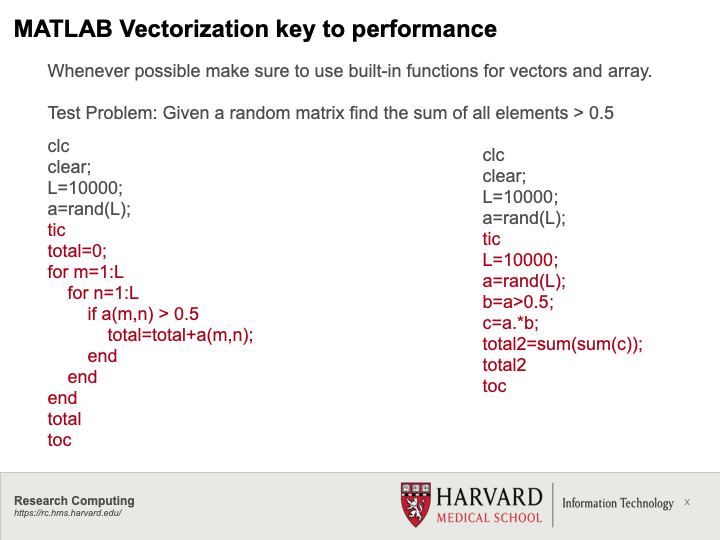

L=10000;
a=rand(L);
tic
total=0;
for m=1:L
    for n=1:L
        if a(m,n) > 0.5
            total=total+a(m,n);
        end
    end
end
total

total = 3.7495e+07

toc

Elapsed time is 2.765496 seconds.


tic
b=a>0.5;
c=a.*b;
total2=sum(sum(c))

total2 = 3.7495e+07

toc

Elapsed time is 0.579781 seconds.


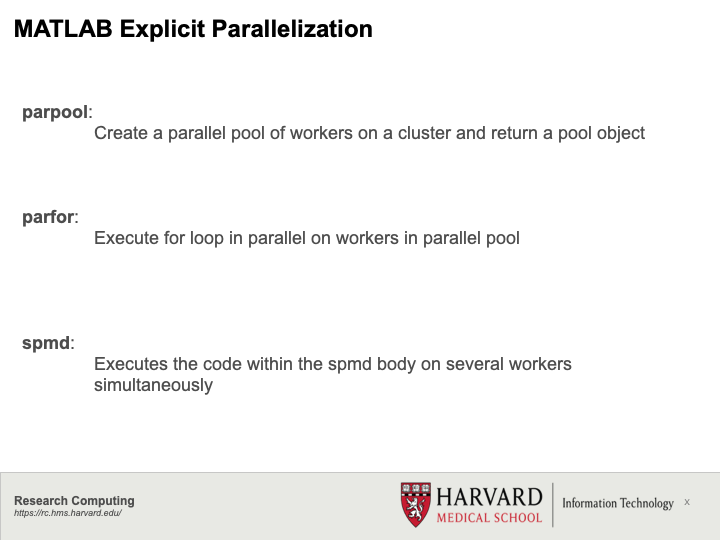

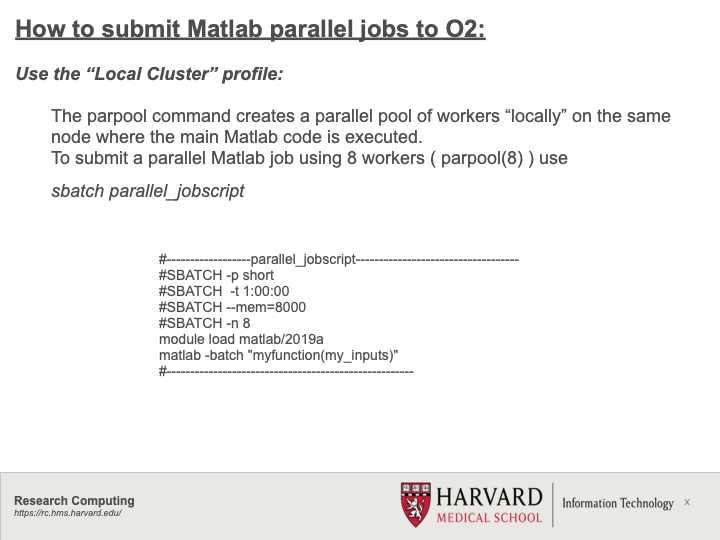

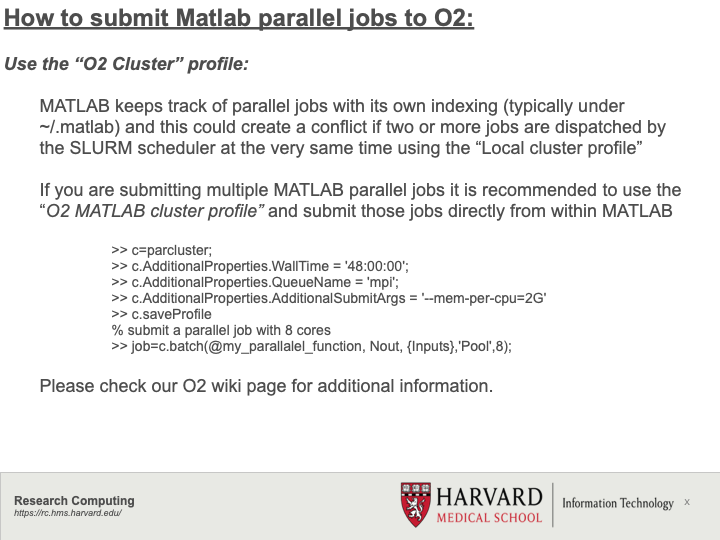

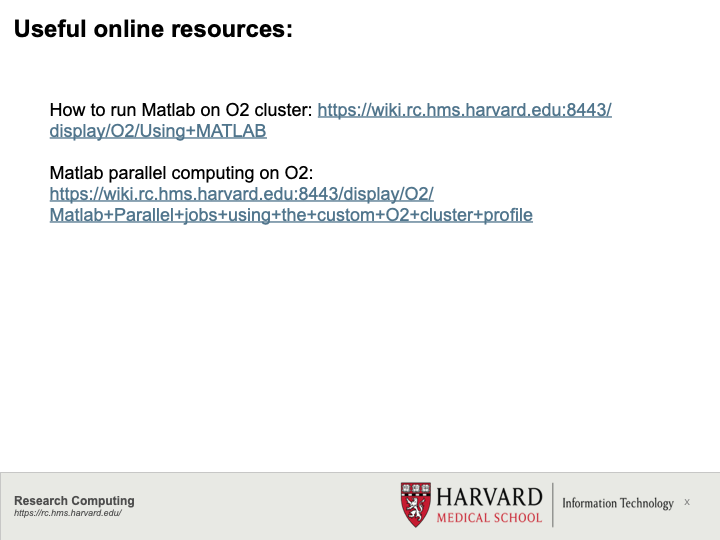

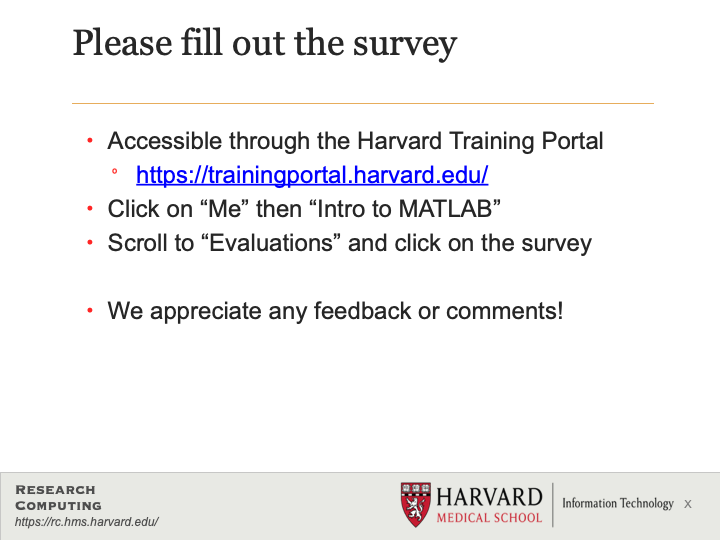

## Functions

function [count,index]=searchit(mystring,mytarget)
  
 % this function returns the total count of mytarget
 index=strfind(mystring,mytarget);  

 number=length(index);
 count=number;
end



If a function is saved as a stand alone file it is important to save the file with the same name as the function. MATLAB automatically searches local path and other specified paths for user-made functions and scripts.

function mult=multiply(val1,val2)
%testreturn
if val1==5
   disp('val1=5 not good') 
   return 
end

mult=val1*val2;

end